# Natick, MA Weather

Current Conditions: Temperature 43.5F, Humidity 36%, Wind 8.1mph


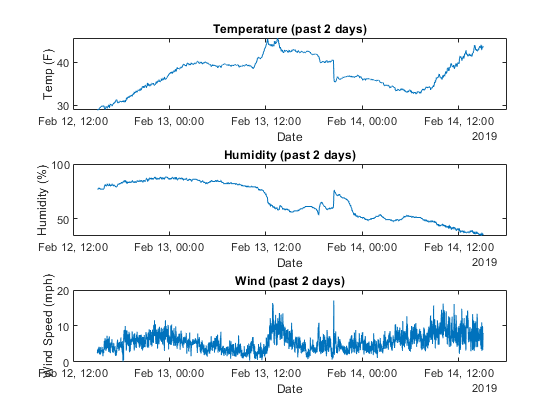

 
data = thingSpeakRead(12397,"NumDays",2,"Timeout",10,"OutputFormat","table");
latestValues = height(data);

useSIUnits = false;

if useSIUnits == 0
    disp("Current Conditions: Temperature " + data.TemperatureF(latestValues) + "F, Humidity " + data.Humidity(latestValues) + "%, Wind " + data.WindSpeedmph(latestValues) + "mph")
    
    plotWeatherData(data.Timestamps, data.TemperatureF, "F", data.WindSpeedmph, "mph", data.Humidity)

else
    tempC = (5/9)*(data.TemperatureF-32);
    tempC = round(tempC,2);
    
    windkmh = data.WindSpeedmph*1.60934;
    disp("Current Conditions: Temperature " + tempC(latestValues) + "C, Humidity " + data.Humidity(latestValues) + "%, Wind " + windkmh(latestValues) + "kph")
    
    plotWeatherData(data.Timestamps, tempC, "C", windkmh, "kph", data.Humidity)
end

function plotWeatherData(timestamps, tempData, tempUnits, windData, windUnits, humidityData)
    subplot(3,1,1)
    plot(timestamps, tempData)
    xlabel("Date")
    ylabel("Temp (" + tempUnits + ")")
    title("Temperature (past 2 days)")
    
    subplot(3,1,2)
    plot(timestamps, humidityData)
    xlabel("Date")
    ylabel("Humidity (%)")
    title("Humidity (past 2 days)")
    
    subplot(3,1,3)
    plot(timestamps, windData)
    xlabel("Date")
    ylabel("Wind Speed (" + windUnits + ")")
    title("Wind (past 2 days)")
end

** To view the code for this example, go to the ****View**** tab and click ****Output on Right**** or ****Output Inline****.*

*Copyright 2019 The MathWorks, Inc.*